# OGLO notebook 4a

hnxj@github

## 1: Time-frequency analysis

- Laminar (vFLIP) + MRI (area thickness, orientation, ...)

- Exponent onset estimation (tau)

- LFP table

clear;clc;close all;

cd('D:\Electrophysiology\Matdelane\');
addpath(genpath('matnwb'));
addpath(genpath('matdelane'));
addpath(genpath('flipv2'));
generateCore();

addpath('fieldtrip');ft_defaults;
nwbPath = "data\";

nwbFiles = {dir(nwbPath).name};
nwbFiles = nwbFiles(endsWith(nwbFiles, ".nwb"));

disp("Toolbox setup done.");

Toolbox setup done.


nPath = "lfpData\";
nFiles = {dir(nPath).name};
nFiles = nFiles(endsWith(nFiles, ".mat"));

z = cell(1, 10);

for i = [1]

    nFile = nFiles{i};
    z{i} = load(nPath + nFile).z;
    disp(num2str(i) + ". loaded : " + nFile);

end

1. loaded : 01_LFPs_OGLO_V1.mat


order : [area{1-10}, cond{1-12}, sess{1-s*}]

- PSpectrums (X, fs, fLim);

- AAAB vs AAAX, BBBA vs BBBX, RRRR vs RRRX spectral analysis (10 areas)

### V1

xG = z{1};

y = squeeze(mean(mean(xG{1, 1}{1}, 1), 2));
frqlims = [0 250];
timeres = 0.2;
overlap = 95;

[p1, f1, t1] = pspectrum(y, 1000, "spectrogram", "FrequencyLimits", frqlims, "TimeResolution", timeres, "OverlapPercent", overlap);
pgx = zeros([12, 128, size(p1)]);
pgxcnt = zeros([12, 15, 128, 2]);

for ik = 1:12 % conditions

    xG1 = xG{1, ik};
    xGc1 = xG{2, ik};

    for jk = 1:size(xG1, 2) % sessions

        xG2 = xG1{jk};
        xGc2 = xGc1{jk}.rfdata;

        qRF = xGc2(:, 4) > 1.0;
        xRF = xGc2(:, 1);
        yRF = xGc2(:, 2);
        rRF = sqrt(xRF.^2 + yRF.^2);

        fovealch = rRF < 2.0;
        pfovealch = (rRF >= 2.0) & (rRF <= 5.0);
        nfovealch = rRF > 5.0;

        for kk = 1:size(xG2, 1) % trial

            for lk = 1:size(xG2, 2) % channel

                pgxcnt(ik, jk, lk, 1) = pgxcnt(ik, jk, lk, 1) + 1;

                if fovealch(lk)

                    pgxcnt(ik, jk, lk, 2) = 1;

                elseif pfovealch(lk)

                    pgxcnt(ik, jk, lk, 2) = 2;

                elseif nfovealch(lk)

                    pgxcnt(ik, jk, lk, 2) = 3;

                else

                    pgxcnt(ik, jk, lk, 2) = -1;

                end
            
            end

        end

    end

    disp("cond : " + num2str(ik));

end

cond : 1
cond : 2
cond : 3
cond : 4
cond : 5
cond : 6
cond : 7
cond : 8
cond : 9
cond : 10
cond : 11
cond : 12


for ik = 1:12 % conditions

    xG1 = xG{1, ik};

    for jk = 1:size(xG1, 2) % sessions

        xG2 = xG1{jk};

        parfor lk = 1:size(xG2, 2) % channel

            y = squeeze(mean(xG2(:, lk, :), 1));
            y = y - mean(y) / std(y);
            [p1temp, f, ~] = pspectrum(y, 1000, "spectrogram", "FrequencyLimits", frqlims, "TimeResolution", timeres, "OverlapPercent", overlap);
            pgx(ik, lk, :, :) = squeeze(pgx(ik, lk, :, :)) + p1temp;
        
        end

        fprintf("ses" + num2str(jk));

    end

    disp("cond : " + num2str(ik));

end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 12 workers.


ses1ses2ses3ses4ses5ses6ses7ses8ses9ses10ses11

cond : 1


ses1ses2ses3ses4ses5ses6ses7ses8ses9ses10ses11

cond : 2


ses1ses2ses3ses4ses5ses6ses7ses8ses9ses10ses11

cond : 3


ses1ses2ses3ses4ses5ses6ses7ses8ses9ses10ses11

cond : 4


ses1ses2ses3ses4ses5ses6ses7ses8ses9ses10ses11

cond : 5


ses1ses2ses3ses4ses5ses6ses7ses8ses9ses10ses11

cond : 6


ses1ses2ses3ses4ses5ses6ses7ses8ses9ses10ses11

cond : 7


ses1ses2ses3ses4ses5ses6ses7ses8ses9ses10ses11

cond : 8


ses1ses2ses3ses4ses5ses6ses7ses8ses9ses10ses11

cond : 9


ses1ses2ses3ses4ses5ses6ses7ses8ses9ses10ses11

cond : 10


ses1ses2ses3ses4ses5ses6ses7ses8ses9ses10ses11

cond : 11


ses1ses2ses3ses4ses5ses6ses7ses8ses9ses10ses11

cond : 12


save("lfpData\TFRs01_OGLO_V1", "pgx", "pgxcnt", "-v7.3");

load("lfpData\TFRs01_OGLO_V1.mat", "pgx", "pgxcnt");
pgx_v1 = pgx;

pgx2 = zeros(size(pgx_v1));

for ik = 1:size(pgx, 2)

    for ij = 1:size(pgx, 1)
    
        for il = 1:size(pgx, 3)
        
            pgx2(ij, ik, il, :) = squeeze((pgx_v1(ij, ik, il, :))/mean(pgx_v1(ij, ik, il, 1:40), "omitnan"));

        end

    end

end

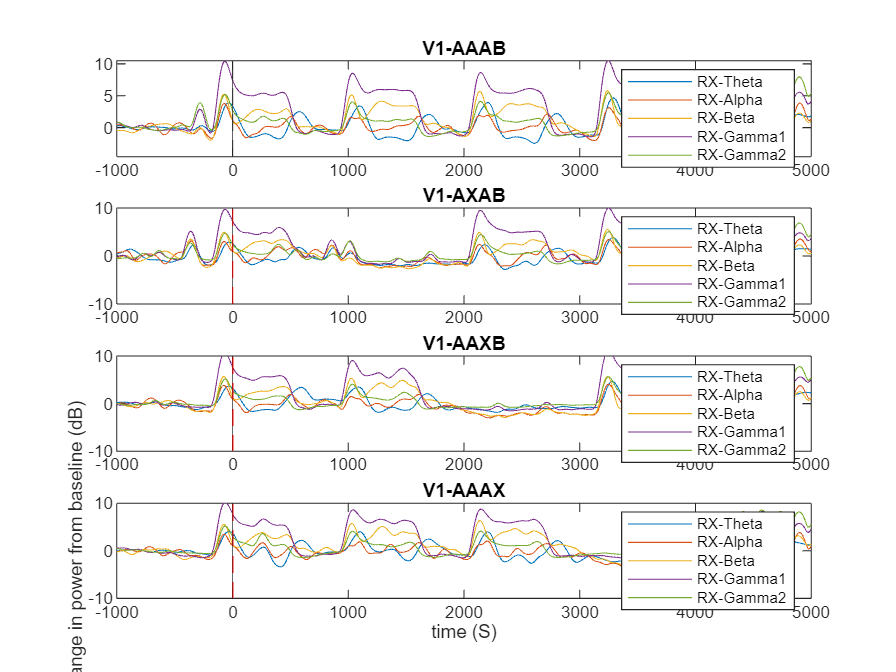

figure;

fmap = linspace(0, 150, 1024);
t = linspace(-1000, 5000, 468);
thetamap = find(fmap > 2, 1):find(fmap > 7, 1);
alphamap = find(fmap > 8, 1):find(fmap > 12, 1);
betamap = find(fmap > 14, 1):find(fmap > 30, 1);
gammamap1 = find(fmap > 32, 1):find(fmap > 64, 1);
gammamap2 = find(fmap > 64, 1):find(fmap >= 150, 1);

subplot(4, 1, 1);
y1t = smooth(squeeze(mean(mean(pgx2(1, :, thetamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1a = smooth(squeeze(mean(mean(pgx2(1, :, alphamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1b = smooth(squeeze(mean(mean(pgx2(1, :, betamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1g1 = smooth(squeeze(mean(mean(pgx2(1, :, gammamap1, :), 2, "omitnan"), 3, "omitnan")), 2);
y1g2 = smooth(squeeze(mean(mean(pgx2(1, :, gammamap2, :), 2, "omitnan"), 3, "omitnan")), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g1)), "DisplayName", "RX-Gamma1");
plot(t, 10*log10((y1g2)), "DisplayName", "RX-Gamma2");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("V1-AAAB");
% ylim([-10 10]);
% xlim([0.4 5.0]);

subplot(4, 1, 2);
y1t = smooth(squeeze(mean(mean(pgx2(2, :, thetamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1a = smooth(squeeze(mean(mean(pgx2(2, :, alphamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1b = smooth(squeeze(mean(mean(pgx2(2, :, betamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1g1 = smooth(squeeze(mean(mean(pgx2(2, :, gammamap1, :), 2, "omitnan"), 3, "omitnan")), 2);
y1g2 = smooth(squeeze(mean(mean(pgx2(2, :, gammamap2, :), 2, "omitnan"), 3, "omitnan")), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g1)), "DisplayName", "RX-Gamma1");
plot(t, 10*log10((y1g2)), "DisplayName", "RX-Gamma2");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(2.000, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(2.500, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("V1-AXAB");ylim([-10 10]);
% xlim([0.4 6.0]);

subplot(4, 1, 3);
y1t = smooth(squeeze(mean(mean(pgx2(3, :, thetamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1a = smooth(squeeze(mean(mean(pgx2(3, :, alphamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1b = smooth(squeeze(mean(mean(pgx2(3, :, betamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1g1 = smooth(squeeze(mean(mean(pgx2(3, :, gammamap1, :), 2, "omitnan"), 3, "omitnan")), 2);
y1g2 = smooth(squeeze(mean(mean(pgx2(3, :, gammamap2, :), 2, "omitnan"), 3, "omitnan")), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g1)), "DisplayName", "RX-Gamma1");
plot(t, 10*log10((y1g2)), "DisplayName", "RX-Gamma2");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(3.031, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(3.531, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("V1-AAXB");ylim([-10 10]);
% xlim([0.4 6.0]);

subplot(4, 1, 4);
y1t = smooth(squeeze(mean(mean(pgx2(4, :, thetamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1a = smooth(squeeze(mean(mean(pgx2(4, :, alphamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1b = smooth(squeeze(mean(mean(pgx2(4, :, betamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1g1 = smooth(squeeze(mean(mean(pgx2(4, :, gammamap1, :), 2, "omitnan"), 3, "omitnan")), 2);
y1g2 = smooth(squeeze(mean(mean(pgx2(4, :, gammamap2, :), 2, "omitnan"), 3, "omitnan")), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g1)), "DisplayName", "RX-Gamma1");
plot(t, 10*log10((y1g2)), "DisplayName", "RX-Gamma2");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(4.062, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(4.562, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
ylabel("Change in power from baseline (dB)");
xlabel("time (S)");
legend();title("V1-AAAX");ylim([-10 10]);
% xlim([0.4 6.0]);

fname = "V1_TFRBandplot";
print(gcf,'-vector','-dsvg',fname +".svg");

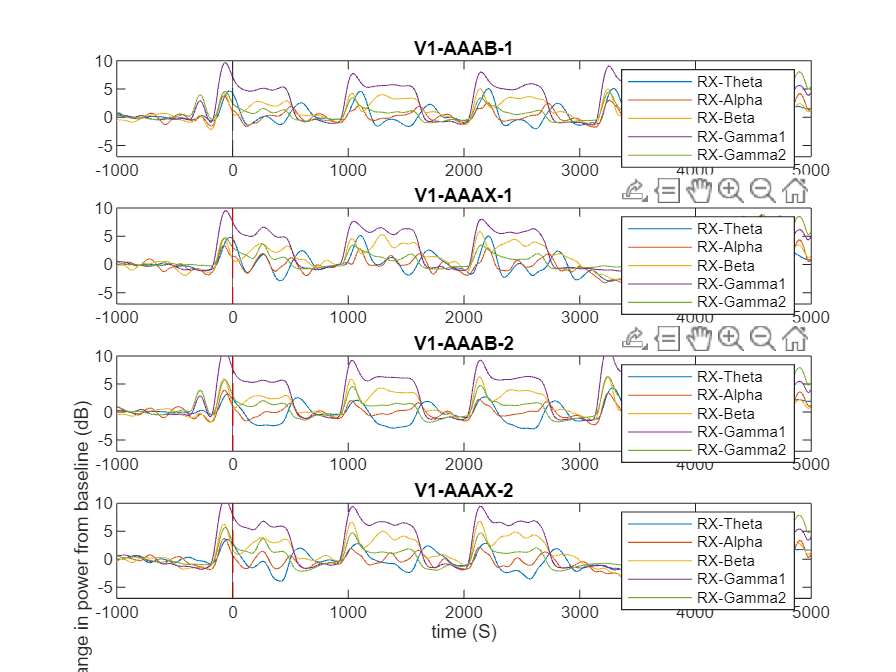

figure;

fmap = linspace(0, 150, 1024);
t = linspace(-1000, 5000, 468);
thetamap = find(fmap > 2, 1):find(fmap > 7, 1);
alphamap = find(fmap > 8, 1):find(fmap > 12, 1);
betamap = find(fmap > 14, 1):find(fmap > 30, 1);
gammamap1 = find(fmap > 32, 1):find(fmap > 64, 1);
gammamap2 = find(fmap > 64, 1):find(fmap >= 150, 1);

nchanxid = 1:30;%pgxcnt(1, 2, :, 2) == 3;

subplot(4, 1, 1);
y1t = smooth(squeeze(mean(mean(pgx2(1, nchanxid, thetamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1a = smooth(squeeze(mean(mean(pgx2(1, nchanxid, alphamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1b = smooth(squeeze(mean(mean(pgx2(1, nchanxid, betamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1g1 = smooth(squeeze(mean(mean(pgx2(1, nchanxid, gammamap1, :), 2, "omitnan"), 3, "omitnan")), 2);
y1g2 = smooth(squeeze(mean(mean(pgx2(1, nchanxid, gammamap2, :), 2, "omitnan"), 3, "omitnan")), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g1)), "DisplayName", "RX-Gamma1");
plot(t, 10*log10((y1g2)), "DisplayName", "RX-Gamma2");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("V1-AAAB-1");
ylim([-7 10]);
% xlim([0.4 5.0]);

subplot(4, 1, 2);
y1t = smooth(squeeze(mean(mean(pgx2(4, nchanxid, thetamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1a = smooth(squeeze(mean(mean(pgx2(4, nchanxid, alphamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1b = smooth(squeeze(mean(mean(pgx2(4, nchanxid, betamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1g1 = smooth(squeeze(mean(mean(pgx2(4, nchanxid, gammamap1, :), 2, "omitnan"), 3, "omitnan")), 2);
y1g2 = smooth(squeeze(mean(mean(pgx2(4, nchanxid, gammamap2, :), 2, "omitnan"), 3, "omitnan")), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g1)), "DisplayName", "RX-Gamma1");
plot(t, 10*log10((y1g2)), "DisplayName", "RX-Gamma2");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(2.000, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(2.500, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("V1-AAAX-1");ylim([-7 10]);
% xlim([0.4 6.0]);

chanxid = 33:64;%pgxcnt(1, 2, :, 2) > 0 & pgxcnt(1, 2, :, 2) < 2;

subplot(4, 1, 3);
y1t = smooth(squeeze(mean(mean(pgx2(1, chanxid, thetamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1a = smooth(squeeze(mean(mean(pgx2(1, chanxid, alphamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1b = smooth(squeeze(mean(mean(pgx2(1, chanxid, betamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1g1 = smooth(squeeze(mean(mean(pgx2(1, chanxid, gammamap1, :), 2, "omitnan"), 3, "omitnan")), 2);
y1g2 = smooth(squeeze(mean(mean(pgx2(1, chanxid, gammamap2, :), 2, "omitnan"), 3, "omitnan")), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g1)), "DisplayName", "RX-Gamma1");
plot(t, 10*log10((y1g2)), "DisplayName", "RX-Gamma2");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(3.031, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(3.531, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("V1-AAAB-2");ylim([-7 10]);
% xlim([0.4 6.0]);

subplot(4, 1, 4);
y1t = smooth(squeeze(mean(mean(pgx2(4, chanxid, thetamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1a = smooth(squeeze(mean(mean(pgx2(4, chanxid, alphamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1b = smooth(squeeze(mean(mean(pgx2(4, chanxid, betamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1g1 = smooth(squeeze(mean(mean(pgx2(4, chanxid, gammamap1, :), 2, "omitnan"), 3, "omitnan")), 2);
y1g2 = smooth(squeeze(mean(mean(pgx2(4, chanxid, gammamap2, :), 2, "omitnan"), 3, "omitnan")), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g1)), "DisplayName", "RX-Gamma1");
plot(t, 10*log10((y1g2)), "DisplayName", "RX-Gamma2");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(4.062, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(4.562, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
ylabel("Change in power from baseline (dB)");
xlabel("time (S)");
legend();title("V1-AAAX-2");ylim([-7 10]);
% xlim([0.4 6.0]);

fname = "V1_TFRBandplot";
print(gcf,'-vector','-dsvg',fname +".svg");

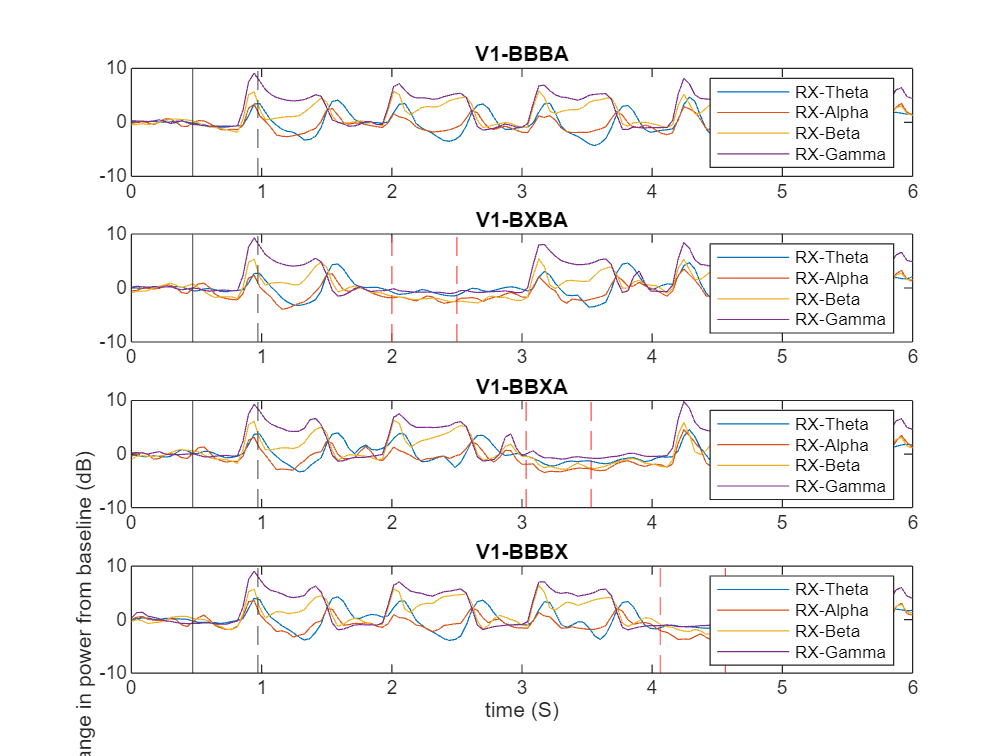

figure;
subplot(4, 1, 1);
y1t = smooth(squeeze(mean(pgx(5, 10:60, :))), 1);
y1a = smooth(squeeze(mean(pgx(5, 80:120, :))), 1);
y1b = smooth(squeeze(mean(pgx(5, 125:320, :))), 1);
y1g = smooth(squeeze(mean(pgx(5, 360:end, :))), 1);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("V1-BBBA");
ylim([-10 10]);
% xlim([0.4 5.0]);

subplot(4, 1, 2);
y1t = smooth(squeeze(mean(pgx(6, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(6, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(6, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(6, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(2.000, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(2.500, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("V1-BXBA");ylim([-10 10]);
% xlim([0.4 6.0]);

subplot(4, 1, 3);
y1t = smooth(squeeze(mean(pgx(7, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(7, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(7, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(7, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(3.031, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(3.531, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("V1-BBXA");ylim([-10 10]);
% xlim([0.4 6.0]);

subplot(4, 1, 4);
y1t = smooth(squeeze(mean(pgx(8, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(8, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(8, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(8, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(4.062, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(4.562, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
ylabel("Change in power from baseline (dB)");
xlabel("time (S)");
legend();title("V1-BBBX");ylim([-10 10]);
% xlim([0.4 6.0]);

fname = "V1_TFRBandplot_2";
print(gcf,'-vector','-dsvg',fname +".svg");

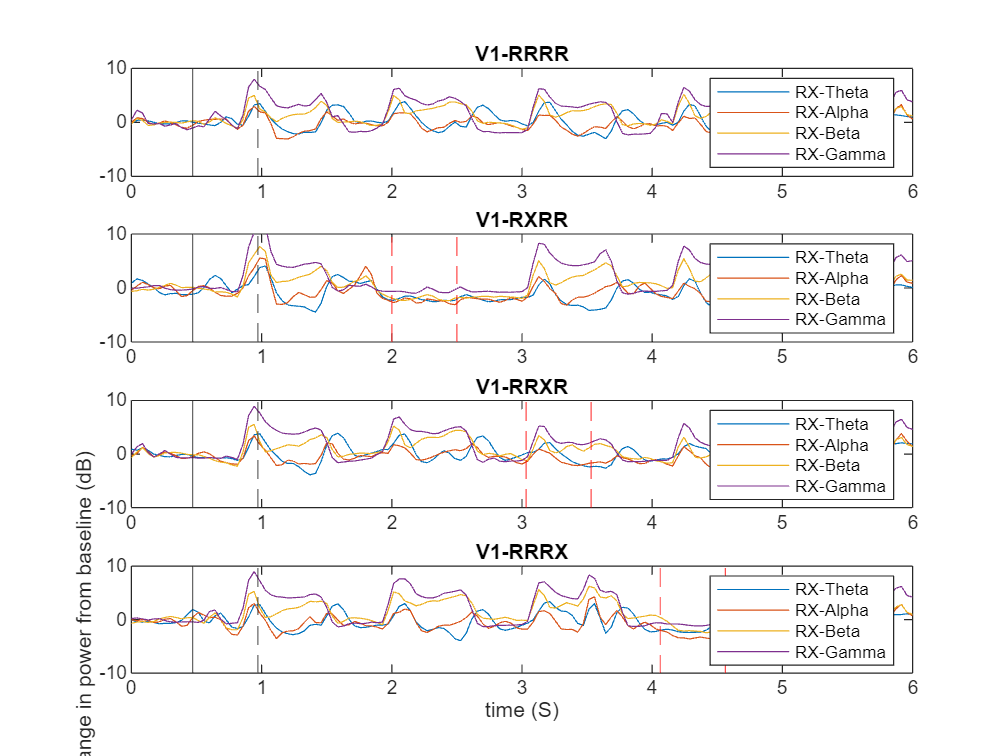

figure;
subplot(4, 1, 1);
y1t = smooth(squeeze(mean(pgx(9, 10:60, :))), 1);
y1a = smooth(squeeze(mean(pgx(9, 80:120, :))), 1);
y1b = smooth(squeeze(mean(pgx(9, 125:320, :))), 1);
y1g = smooth(squeeze(mean(pgx(9, 360:end, :))), 1);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("V1-RRRR");
ylim([-10 10]);
% xlim([0.4 5.0]);

subplot(4, 1, 2);
y1t = smooth(squeeze(mean(pgx(10, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(10, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(10, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(10, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(2.000, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(2.500, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("V1-RXRR");ylim([-10 10]);
% xlim([0.4 6.0]);

subplot(4, 1, 3);
y1t = smooth(squeeze(mean(pgx(11, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(11, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(11, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(11, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(3.031, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(3.531, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("V1-RRXR");ylim([-10 10]);
% xlim([0.4 6.0]);

subplot(4, 1, 4);
y1t = smooth(squeeze(mean(pgx(12, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(12, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(12, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(12, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(4.062, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(4.562, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
ylabel("Change in power from baseline (dB)");
xlabel("time (S)");
legend();title("V1-RRRX");ylim([-10 10]);
% xlim([0.4 6.0]);

fname = "V1_TFRBandplot_3";
print(gcf,'-vector','-dsvg',fname +".svg");

### V2

xG = z{2};

y = squeeze(mean(mean(xG{1, 1}{1}, 1), 2));
frqlims = [0 150];
timeres = 0.4;
overlap = 97;

[p1, f1, t1] = pspectrum(y, 1000, "spectrogram", "FrequencyLimits", frqlims, "TimeResolution", timeres, "OverlapPercent", overlap);
pgx = zeros([12, 128, size(p1)]);
pgxcnt = zeros([12, 15, 128, 2]);

for ik = 1:12 % conditions

    xG1 = xG{1, ik};
    xGc1 = xG{2, ik};

    for jk = 1:size(xG1, 2) % sessions

        xG2 = xG1{jk};
        xGc2 = xGc1{jk}.rfdata;

        qRF = xGc2(:, 4) > 1.0;
        xRF = xGc2(:, 1);
        yRF = xGc2(:, 2);
        rRF = sqrt(xRF.^2 + yRF.^2);

        fovealch = rRF < 2.0;
        pfovealch = (rRF >= 2.0) & (rRF <= 5.0);
        nfovealch = rRF > 5.0;

        for kk = 1:size(xG2, 1) % trial

            for lk = 1:size(xG2, 2) % channel

                pgxcnt(ik, jk, lk, 1) = pgxcnt(ik, jk, lk, 1) + 1;

                if fovealch(lk)

                    pgxcnt(ik, jk, lk, 2) = 1;

                elseif pfovealch(lk)

                    pgxcnt(ik, jk, lk, 2) = 2;

                elseif nfovealch(lk)

                    pgxcnt(ik, jk, lk, 2) = 3;

                else

                    pgxcnt(ik, jk, lk, 2) = -1;

                end
            
            end

        end

    end

    disp("cond : " + num2str(ik));

end

cond : 1
cond : 2
cond : 3
cond : 4
cond : 5
cond : 6
cond : 7
cond : 8
cond : 9
cond : 10
cond : 11
cond : 12


for ik = 1:12 % conditions

    xG1 = xG{1, ik};

    for jk = 1:size(xG1, 2) % sessions

        xG2 = xG1{jk};

        for kk = 1:size(xG2, 1) % trial

            parfor lk = 1:size(xG2, 2) % channel

                y = squeeze(xG2(kk, lk, :));
                y = y - mean(y) / std(y);
                [p1temp, f, ~] = pspectrum(y, 1000, "spectrogram", "FrequencyLimits", frqlims, "TimeResolution", timeres, "OverlapPercent", overlap);
                pgx(ik, lk, :, :) = squeeze(pgx(ik, lk, :, :)) + p1temp;
            
            end

        end

        fprintf("ses" + num2str(jk));

    end

    disp("cond : " + num2str(ik));

end

ses1ses2ses3ses4ses5ses6ses7ses8ses9ses10ses11ses12ses13

cond : 1


ses1ses2ses3ses4ses5ses6ses7ses8ses9ses10ses11ses12ses13

cond : 2


ses1ses2ses3ses4ses5ses6ses7ses8ses9ses10ses11ses12ses13

cond : 3


ses1ses2ses3ses4ses5ses6ses7ses8ses9ses10ses11ses12ses13

cond : 4


ses1ses2ses3ses4ses5ses6ses7ses8ses9ses10ses11ses12ses13

cond : 5


ses1ses2ses3ses4ses5ses6ses7ses8ses9ses10ses11ses12ses13

cond : 6


ses1ses2ses3ses4ses5ses6ses7ses8ses9ses10ses11ses12ses13

cond : 7


ses1ses2ses3ses4ses5ses6ses7ses8ses9ses10ses11ses12ses13

cond : 8


ses1ses2ses3ses4ses5ses6ses7ses8ses9ses10ses11ses12ses13

cond : 9


ses1ses2ses3ses4ses5ses6ses7ses8ses9ses10ses11ses12ses13

cond : 10


ses1ses2ses3ses4ses5ses6ses7ses8ses9ses10ses11ses12ses13

cond : 11


ses1ses2ses3ses4ses5ses6ses7ses8ses9ses10ses11ses12ses13

cond : 12


y = squeeze(mean(xG3(:, 21, :), 1));
pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.25, "OverlapPercent", 90);

save("lfpData\TFRs02_OGLO_V2", "pgx", "pgxcnt", "-v7.3");

load("lfpData\TFRs02_OGLO_V2.mat", "pgx", "pgxcnt");
pgx_v2 = pgx;

pgx2 = zeros(size(pgx_v2));

for ik = 1:size(pgx, 2)

    for ij = 1:size(pgx, 1)
    
        for il = 1:size(pgx, 3)
        
            pgx2(ij, ik, il, :) = squeeze((pgx_v2(ij, ik, il, :))/mean(pgx_v2(ij, ik, il, 1:40), "omitnan"));

        end

    end

end

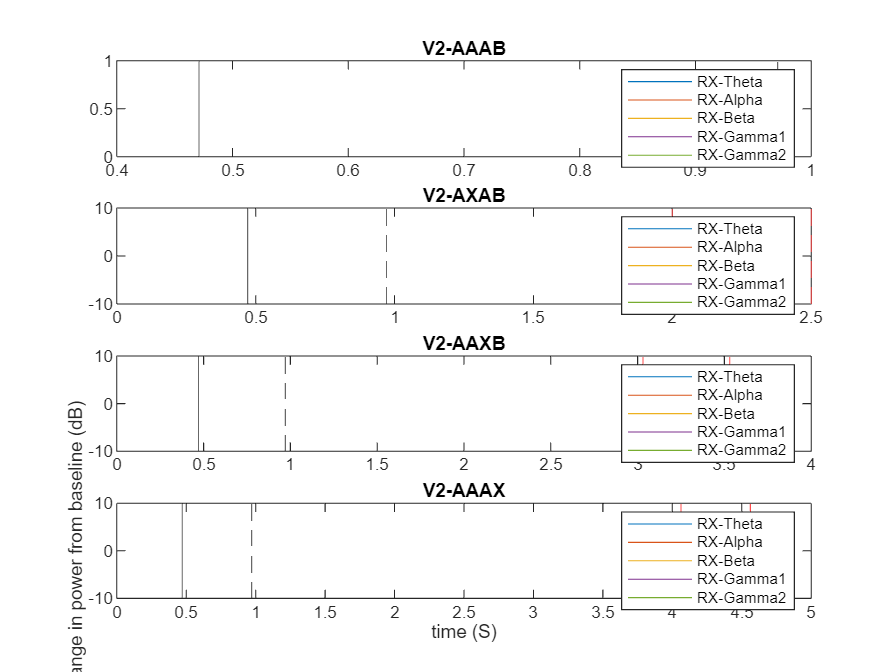

figure;

fmap = linspace(0, 150, 1024);
t = linspace(-1000, 5000, 468);
thetamap = find(fmap > 2, 1):find(fmap > 7, 1);
alphamap = find(fmap > 8, 1):find(fmap > 12, 1);
betamap = find(fmap > 14, 1):find(fmap > 30, 1);
gammamap1 = find(fmap > 32, 1):find(fmap > 64, 1);
gammamap2 = find(fmap > 64, 1):find(fmap >= 150, 1);

subplot(4, 1, 1);
y1t = smooth(squeeze(mean(mean(pgx2(1, :, thetamap, :), 2), 3)), 2);
y1a = smooth(squeeze(mean(mean(pgx2(1, :, alphamap, :), 2), 3)), 2);
y1b = smooth(squeeze(mean(mean(pgx2(1, :, betamap, :), 2), 3)), 2);
y1g1 = smooth(squeeze(mean(mean(pgx2(1, :, gammamap1, :), 2), 3)), 2);
y1g2 = smooth(squeeze(mean(mean(pgx2(1, :, gammamap2, :), 2), 3)), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g1)), "DisplayName", "RX-Gamma1");
plot(t, 10*log10((y1g2)), "DisplayName", "RX-Gamma2");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("V2-AAAB");
ylim([-10 10]);
% xlim([0.4 5.0]);

subplot(4, 1, 2);
y1t = smooth(squeeze(mean(mean(pgx2(2, :, thetamap, :), 2), 3)), 2);
y1a = smooth(squeeze(mean(mean(pgx2(2, :, alphamap, :), 2), 3)), 2);
y1b = smooth(squeeze(mean(mean(pgx2(2, :, betamap, :), 2), 3)), 2);
y1g1 = smooth(squeeze(mean(mean(pgx2(2, :, gammamap1, :), 2), 3)), 2);
y1g2 = smooth(squeeze(mean(mean(pgx2(2, :, gammamap2, :), 2), 3)), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g1)), "DisplayName", "RX-Gamma1");
plot(t, 10*log10((y1g2)), "DisplayName", "RX-Gamma2");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(2.000, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(2.500, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("V2-AXAB");ylim([-10 10]);
% xlim([0.4 6.0]);

subplot(4, 1, 3);
y1t = smooth(squeeze(mean(mean(pgx2(3, :, thetamap, :), 2), 3)), 2);
y1a = smooth(squeeze(mean(mean(pgx2(3, :, alphamap, :), 2), 3)), 2);
y1b = smooth(squeeze(mean(mean(pgx2(3, :, betamap, :), 2), 3)), 2);
y1g1 = smooth(squeeze(mean(mean(pgx2(3, :, gammamap1, :), 2), 3)), 2);
y1g2 = smooth(squeeze(mean(mean(pgx2(3, :, gammamap2, :), 2), 3)), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g1)), "DisplayName", "RX-Gamma1");
plot(t, 10*log10((y1g2)), "DisplayName", "RX-Gamma2");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(3.031, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(3.531, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("V2-AAXB");ylim([-10 10]);
% xlim([0.4 6.0]);

subplot(4, 1, 4);
y1t = smooth(squeeze(mean(mean(pgx2(4, :, thetamap, :), 2), 3)), 2);
y1a = smooth(squeeze(mean(mean(pgx2(4, :, alphamap, :), 2), 3)), 2);
y1b = smooth(squeeze(mean(mean(pgx2(4, :, betamap, :), 2), 3)), 2);
y1g1 = smooth(squeeze(mean(mean(pgx2(4, :, gammamap1, :), 2), 3)), 2);
y1g2 = smooth(squeeze(mean(mean(pgx2(4, :, gammamap2, :), 2), 3)), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g1)), "DisplayName", "RX-Gamma1");
plot(t, 10*log10((y1g2)), "DisplayName", "RX-Gamma2");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(4.062, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(4.562, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
ylabel("Change in power from baseline (dB)");
xlabel("time (S)");
legend();title("V2-AAAX");ylim([-10 10]);
% xlim([0.4 6.0]);

fname = "V2_TFRBandplot";
print(gcf,'-vector','-dsvg',fname +".svg");

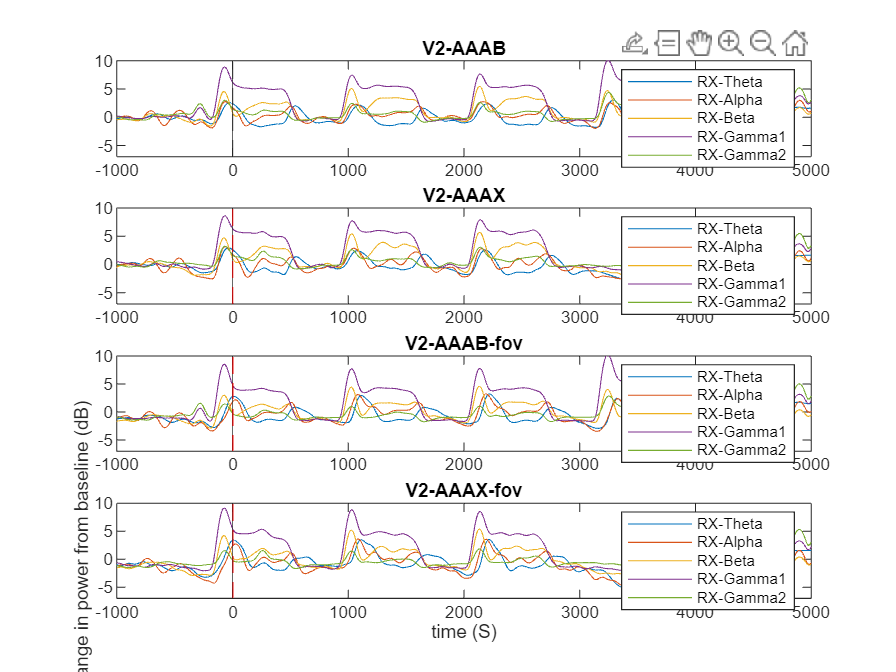

figure;

fmap = linspace(0, 150, 1024);
t = linspace(-1000, 5000, 468);
thetamap = find(fmap > 2, 1):find(fmap > 7, 1);
alphamap = find(fmap > 8, 1):find(fmap > 12, 1);
betamap = find(fmap > 14, 1):find(fmap > 30, 1);
gammamap1 = find(fmap > 32, 1):find(fmap > 64, 1);
gammamap2 = find(fmap > 64, 1):find(fmap >= 150, 1);

nchanxid = 1:30;%pgxcnt(1, 2, :, 2) == 3;

subplot(4, 1, 1);
y1t = smooth(squeeze(mean(mean(pgx2(1, nchanxid, thetamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1a = smooth(squeeze(mean(mean(pgx2(1, nchanxid, alphamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1b = smooth(squeeze(mean(mean(pgx2(1, nchanxid, betamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1g1 = smooth(squeeze(mean(mean(pgx2(1, nchanxid, gammamap1, :), 2, "omitnan"), 3, "omitnan")), 2);
y1g2 = smooth(squeeze(mean(mean(pgx2(1, nchanxid, gammamap2, :), 2, "omitnan"), 3, "omitnan")), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g1)), "DisplayName", "RX-Gamma1");
plot(t, 10*log10((y1g2)), "DisplayName", "RX-Gamma2");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("V2-AAAB-1");
ylim([-7 10]);
% xlim([0.4 5.0]);

subplot(4, 1, 2);
y1t = smooth(squeeze(mean(mean(pgx2(4, nchanxid, thetamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1a = smooth(squeeze(mean(mean(pgx2(4, nchanxid, alphamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1b = smooth(squeeze(mean(mean(pgx2(4, nchanxid, betamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1g1 = smooth(squeeze(mean(mean(pgx2(4, nchanxid, gammamap1, :), 2, "omitnan"), 3, "omitnan")), 2);
y1g2 = smooth(squeeze(mean(mean(pgx2(4, nchanxid, gammamap2, :), 2, "omitnan"), 3, "omitnan")), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g1)), "DisplayName", "RX-Gamma1");
plot(t, 10*log10((y1g2)), "DisplayName", "RX-Gamma2");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(2.000, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(2.500, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("V2-AAAX-1");ylim([-7 10]);
% xlim([0.4 6.0]);

chanxid = 33:64;%pgxcnt(1, 2, :, 2) > 0 & pgxcnt(1, 2, :, 2) < 2;

subplot(4, 1, 3);
y1t = smooth(squeeze(mean(mean(pgx2(1, chanxid, thetamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1a = smooth(squeeze(mean(mean(pgx2(1, chanxid, alphamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1b = smooth(squeeze(mean(mean(pgx2(1, chanxid, betamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1g1 = smooth(squeeze(mean(mean(pgx2(1, chanxid, gammamap1, :), 2, "omitnan"), 3, "omitnan")), 2);
y1g2 = smooth(squeeze(mean(mean(pgx2(1, chanxid, gammamap2, :), 2, "omitnan"), 3, "omitnan")), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g1)), "DisplayName", "RX-Gamma1");
plot(t, 10*log10((y1g2)), "DisplayName", "RX-Gamma2");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(3.031, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(3.531, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("V2-AAAB-2");ylim([-7 10]);
% xlim([0.4 6.0]);

subplot(4, 1, 4);
y1t = smooth(squeeze(mean(mean(pgx2(4, chanxid, thetamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1a = smooth(squeeze(mean(mean(pgx2(4, chanxid, alphamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1b = smooth(squeeze(mean(mean(pgx2(4, chanxid, betamap, :), 2, "omitnan"), 3, "omitnan")), 2);
y1g1 = smooth(squeeze(mean(mean(pgx2(4, chanxid, gammamap1, :), 2, "omitnan"), 3, "omitnan")), 2);
y1g2 = smooth(squeeze(mean(mean(pgx2(4, chanxid, gammamap2, :), 2, "omitnan"), 3, "omitnan")), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g1)), "DisplayName", "RX-Gamma1");
plot(t, 10*log10((y1g2)), "DisplayName", "RX-Gamma2");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(4.062, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(4.562, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
ylabel("Change in power from baseline (dB)");
xlabel("time (S)");
legend();title("V2-AAAX-2");ylim([-7 10]);
% xlim([0.4 6.0]);

fname = "V2_TFRBandplot";
print(gcf,'-vector','-dsvg',fname +".svg");

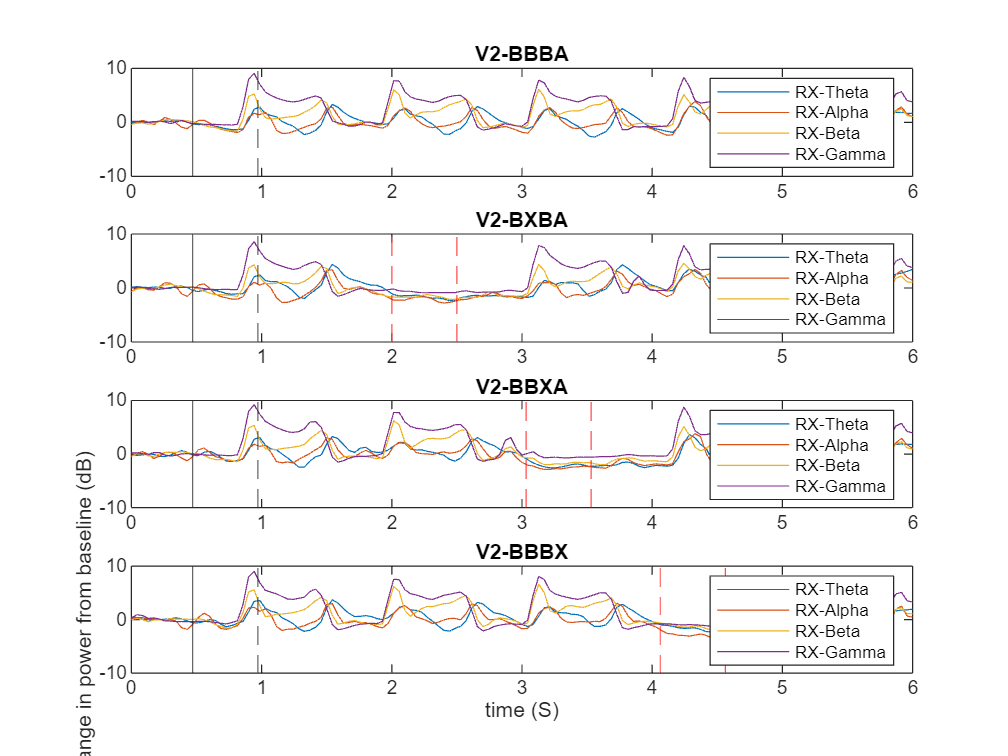

figure;
subplot(4, 1, 1);
y1t = smooth(squeeze(mean(pgx(5, 10:60, :))), 1);
y1a = smooth(squeeze(mean(pgx(5, 80:120, :))), 1);
y1b = smooth(squeeze(mean(pgx(5, 125:320, :))), 1);
y1g = smooth(squeeze(mean(pgx(5, 360:end, :))), 1);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("V2-BBBA");
ylim([-10 10]);
% xlim([0.4 5.0]);

subplot(4, 1, 2);
y1t = smooth(squeeze(mean(pgx(6, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(6, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(6, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(6, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(2.000, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(2.500, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("V2-BXBA");ylim([-10 10]);
% xlim([0.4 6.0]);

subplot(4, 1, 3);
y1t = smooth(squeeze(mean(pgx(7, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(7, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(7, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(7, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(3.031, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(3.531, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("V2-BBXA");ylim([-10 10]);
% xlim([0.4 6.0]);

subplot(4, 1, 4);
y1t = smooth(squeeze(mean(pgx(8, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(8, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(8, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(8, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(4.062, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(4.562, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
ylabel("Change in power from baseline (dB)");
xlabel("time (S)");
legend();title("V2-BBBX");ylim([-10 10]);
% xlim([0.4 6.0]);

fname = "V2_TFRBandplot_2";
print(gcf,'-vector','-dsvg',fname +".svg");

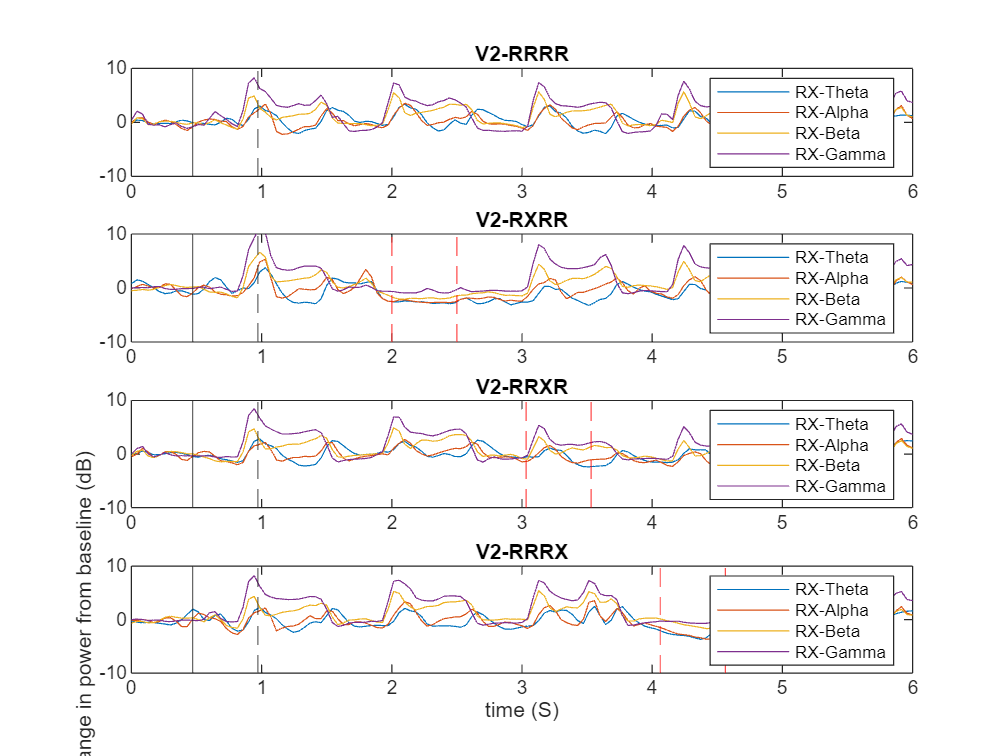

figure;
subplot(4, 1, 1);
y1t = smooth(squeeze(mean(pgx(9, 10:60, :))), 1);
y1a = smooth(squeeze(mean(pgx(9, 80:120, :))), 1);
y1b = smooth(squeeze(mean(pgx(9, 125:320, :))), 1);
y1g = smooth(squeeze(mean(pgx(9, 360:end, :))), 1);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("V2-RRRR");
ylim([-10 10]);
% xlim([0.4 5.0]);

subplot(4, 1, 2);
y1t = smooth(squeeze(mean(pgx(10, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(10, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(10, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(10, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(2.000, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(2.500, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("V2-RXRR");ylim([-10 10]);
% xlim([0.4 6.0]);

subplot(4, 1, 3);
y1t = smooth(squeeze(mean(pgx(11, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(11, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(11, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(11, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(3.031, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(3.531, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("V2-RRXR");ylim([-10 10]);
% xlim([0.4 6.0]);

subplot(4, 1, 4);
y1t = smooth(squeeze(mean(pgx(12, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(12, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(12, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(12, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(4.062, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(4.562, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
ylabel("Change in power from baseline (dB)");
xlabel("time (S)");
legend();title("V2-RRRX");ylim([-10 10]);
% xlim([0.4 6.0]);

fname = "V2_TFRBandplot_3";
print(gcf,'-vector','-dsvg',fname +".svg");

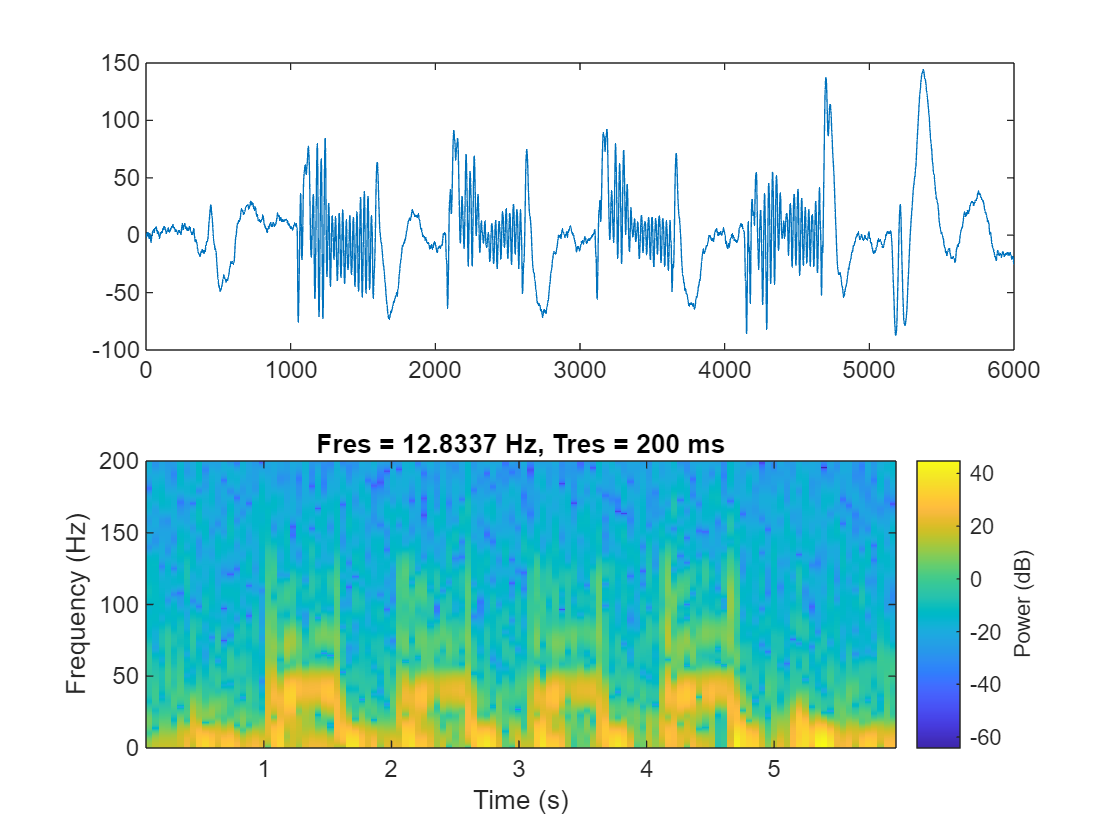

function Y = mvpa_weights(X, G)
% MVPA_WEIGHTS - Perform multivariate pattern analysis (MVPA) using SVM
% Inputs:
%   X - Data matrix (N groups x M channels x T time points)
%   G - Group labels (1 x N group labels)
% Outputs:
%   Y - Weight matrix (N groups x M channels)

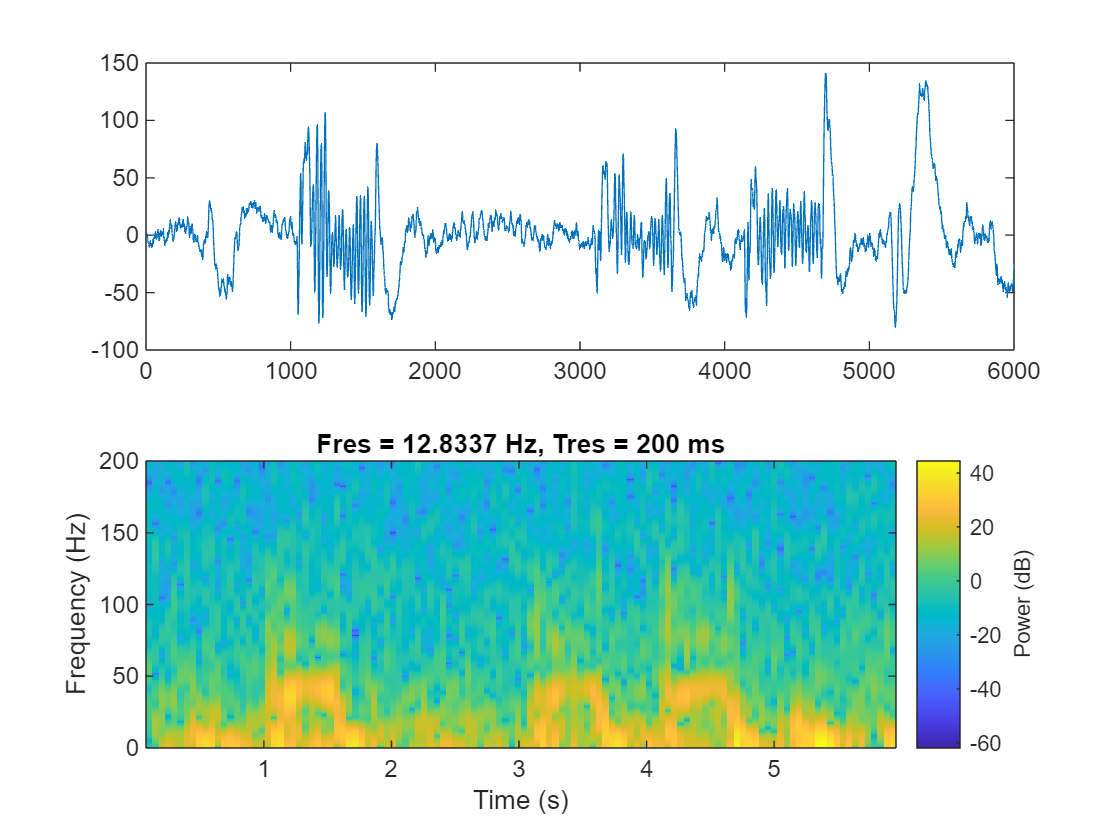


% Dimensions
[N, M, T] = size(X);

% Reshape data into 2D matrix for SVM
X_flat = reshape(X, [N, M * T]);

% Initialize weight matrix

Y = zeros(N, M);

% Perform MVPA for each group
for i = 1:N
    % Create binary labels for the current group
    labels = double(G == i);
    labels(labels == 0) = -1; % SVM requires binary labels -1 and 1
    
    % Train linear SVM
    SVMModel = fitcsvm(X_flat, labels, 'KernelFunction', 'linear', ...
                       'Standardize', true, 'ClassNames', [-1, 1]);
    
    % Extract weights for the linear classifier
    beta = SVMModel.Beta; % Coefficients for M*T features
    
    % Reshape weights back to M channels
    Y(i, :) = sum(reshape(beta, [M, T]), 2); % Sum over time dimension
end

end

t = linspace(-1, 5, 6000);
y = squeeze(mean(xG1(:, 1, :), 1));
% y = conv(y, [-1 2 -1], "same");
subplot(2, 1, 1);
plot(y);
subplot(2, 1, 2);
pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 200], "TimeResolution", 0.2);

t = linspace(-1, 5, 6000);
y = squeeze(mean(xG2(:, 1, :), 1));
% y = conv(y, [-1 2 -1], "same");
subplot(2, 1, 1);
plot(y);
subplot(2, 1, 2);
pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 200], "TimeResolution", 0.2);

## End